# runXilinxSim

© 2020 The MathWorks, Inc.

Generates HDL and testbench, and runs HDL simulation using Xilinx® Vivado® Simulator or ISIM

## Syntax

For more information, see the function [help page](matlab:doc('runXilinxSim')).

## Requirements

Xilinx Vivado or ISE is required to use this function.

## Example

Add Xilinx Vivado to your system path (once per MATLAB session). Modify `toolPath` to match your system settings as needed.

toolPath = 'C:\Xilinx\Vivado\2017.4\bin';
hdlsetuptoolpath('ToolName', 'Xilinx Vivado', 'ToolPath', toolPath);

Open the sfir_fixed model from the HDL Coder examples.

model = 'sfir_fixed';
open_system(model);

Use `runXilinxSim` to automatically generates HDL for the DUT and simulates the generated HDL in Vivado Simulator.

hdlset_param(model,'TargetDirectory',tempname);
dut = 'sfir_fixed/symmetric_fir';
runXilinxSim(dut);

You should see Vivado simulation result similar to the following figure.

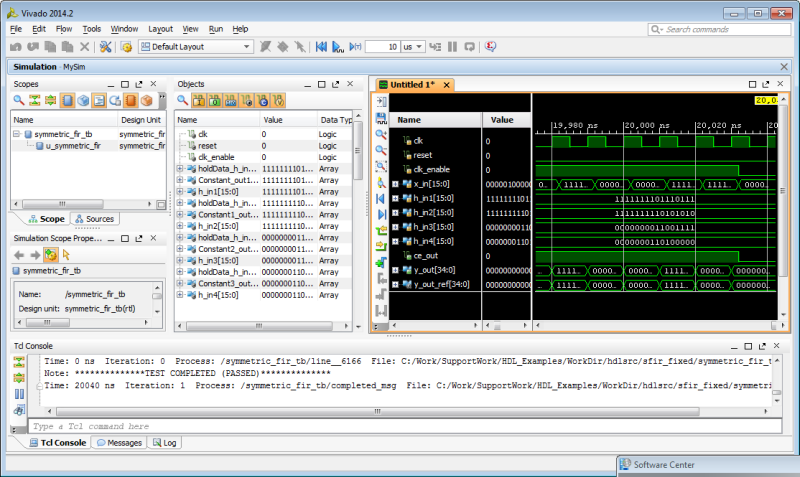

This concludes the example.

close_system(model,0);